# Exercises 4.1

3. Nodal coordinates of a 1D element are:x1= 2.0,x2= 10.0andx3= 9.0. Plot the JacobianJon the natural coordinatesspace and explain the behavior between nodes 2 and 3.

clear all
clc

n = 101;
xi = linspace (-1, 1, n);

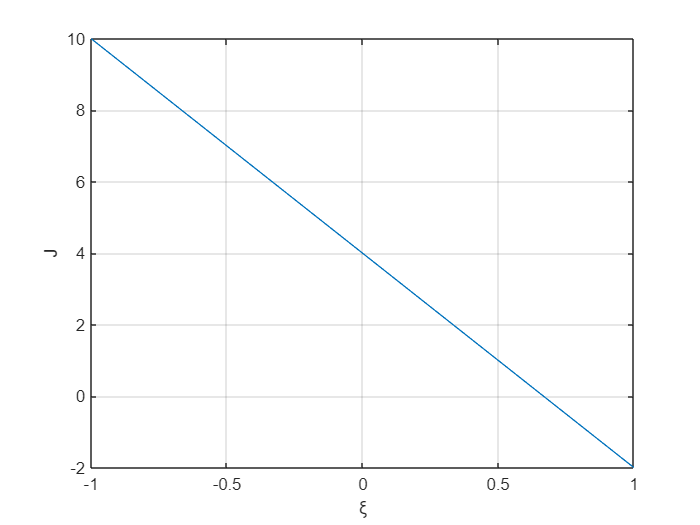

C = [2; 10; 9];
for i = 1:n
    J(i, 1) = C'* lin_deriv (xi(i));
end
plot(xi, J)
ylabel ("J")
xlabel ("ξ")
grid on

function dn = lin_deriv (xi)
dn = [xi - 1/2
      xi + 1/2
      -2*xi];
end